**1. Suponha que observa o estado do tempo uma vez por dia (por exemplo, de manhã às 9:00) e que considera**

**três estados possíveis: sol, nuvens e chuva. Assumindo que o tempo no dia n + 1 apenas depende do**

**tempo no dia n e que as probabilidades de transição são as da tabela seguinte, responda às questões**

**abaixo:**

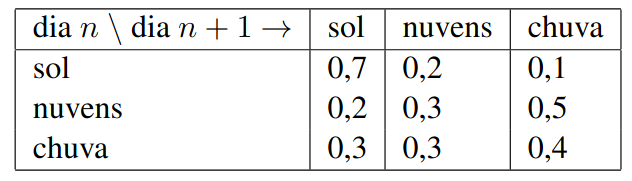

**(a)** Desenhe a representação gráfica da cadeia;

**(b)** Defina, em Matlab, a correspondente matriz de transição;

T = [7 2 3; % <-- Sol
    2 3 3 % <-- Nuvens
    1 5 4]/10 % <-- Chuva

T =     0.7000    0.2000    0.3000
    0.2000    0.3000    0.3000
    0.1000    0.5000    0.4000


**(c)** Assumindo que a observação inicial (digamos no dia 0) é que o dia é de sol, qual a probabilidade

do dia 2 ser de chuva ?

x_0 = [1 0 0]';

x_2 = T^2 * x_0;

disp("Probabilidade do dia 2 ser de chuva: " + x_2(3, 1))

Probabilidade do dia 2 ser de chuva: 0.21


**(d)** Calcule as n primeiras potências de T (n=20) e apresente num gráfico a evolução dos vários elementos da matriz em função de n;

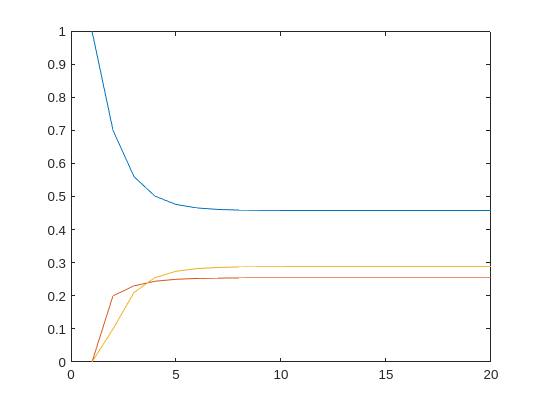

y = zeros(3, 20);
y(:, 1) = x_0;

for n = 1:19
    y(:, n+1) = T^n * x_0;
end

plot(1:20, y)

**(e)** Repita o processo da alínea anterior parando-o assim que o máximo do módulo da diferença entre

os valores dos elementos da matriz em duas iterações consecutivas não exceda 10^(−4);

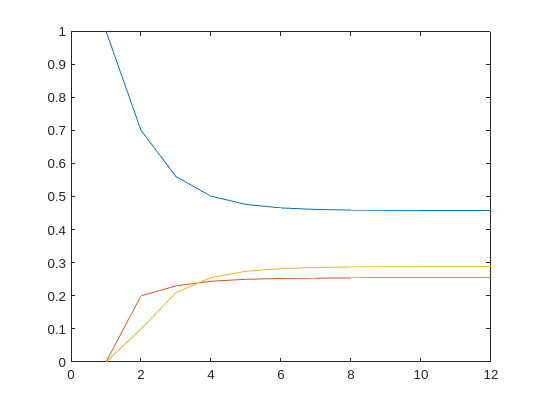

y = x_0;

for n = 1:19
    y(:, n+1) = T^n * x_0;
    if max(abs(y(:, n) - y(:, n+1))) < 10^(-4)
        break
    end
end

plot(1:length(y), y)


disp("Probabilidade de Sol no vetor estacionário calculado experimentalmente: " + y(1, length(y)));

Probabilidade de Sol no vetor estacionário calculado experimentalmente: 0.45767


disp("Probabilidade de Nuvens no vetor estacionário calculado experimentalmente: " + y(2, length(y)));

Probabilidade de Nuvens no vetor estacionário calculado experimentalmente: 0.25423


disp("Probabilidade de Chuva no vetor estacionário calculado experimentalmente: " + y(3, length(y)));

Probabilidade de Chuva no vetor estacionário calculado experimentalmente: 0.2881


**(f)** Confirme o valor obtido na alínea anterior, calculando o vetor estado em regime estacionário usando

um método não iterativo.

M = [T - eye(length(T));
    ones(1, length(T))];

n = zeros(length(T), 1);
n(length(T) + 1, 1) = 1;

u = M\n;

disp("Probabilidade de Sol no vetor estacionário calculado teoricamente: " + u(1, 1));

Probabilidade de Sol no vetor estacionário calculado teoricamente: 0.45763


disp("Probabilidade de Nuvens no vetor estacionário calculado teoricamente: " + u(2, 1));

Probabilidade de Nuvens no vetor estacionário calculado teoricamente: 0.25424


disp("Probabilidade de Chuva no vetor estacionário calculado teoricamente: " + u(3, 1));

Probabilidade de Chuva no vetor estacionário calculado teoricamente: 0.28814


2. Considere o seguinte conjunto de páginas web ligadas entre si:

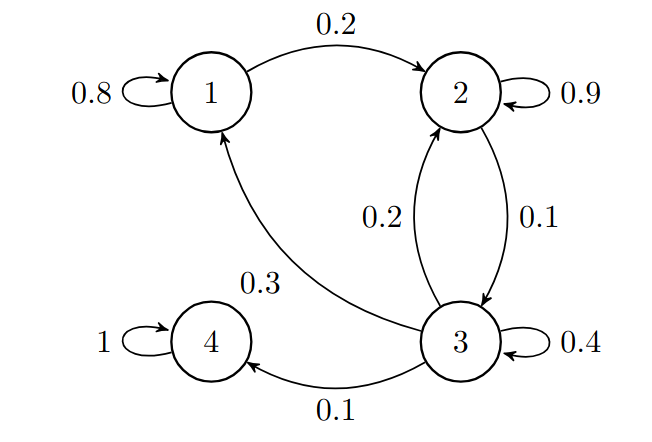

**(a)** Escreva a matriz de transição H (de Hyperlinks), com H_ji� sendo a probabilidade de ir da página i para a página j em um único passo. Crie em MATLAB essa matriz.

T = [8 0 3 0;
    2 9 2 0;
    0 1 4 0;
    0 0 1 10]/10

T =     0.8000         0    0.3000         0
    0.2000    0.9000    0.2000         0
         0    0.1000    0.4000         0
         0         0    0.1000    1.0000


**(b)** Qual é a probabilidade de, começando na página 1, ao fim de 1000 passos, estar na página 2? Este valor estava dentro da sua expectativa?

x_0 = [1 0 0 0]'

x_0 =      1
     0
     0
     0



x_1000 = T^1000 * x_0

x_1000 =     0.0000
    0.0000
    0.0000
    1.0000



disp("Probabilidade de estar na pagina 2 após 1000 passos: " + x_1000(2, 1));

Probabilidade de estar na pagina 2 após 1000 passos: 5.181e-06


**(c)** Determine a probabilidade de chegar à página j a partir da página i, em 1, 2, 10 e 100 passos.

% Para 1 passo
disp("Após 1 passo: ")

Após 1 passo: 


disp(T)

    0.8000         0    0.3000         0
    0.2000    0.9000    0.2000         0
         0    0.1000    0.4000         0
         0         0    0.1000    1.0000




% Para 2 passos
disp("Após 2 passo: ")

Após 2 passo: 


disp(T^2)

    0.6400    0.0300    0.3600         0
    0.3400    0.8300    0.3200         0
    0.0200    0.1300    0.1800         0
         0    0.0100    0.1400    1.0000




% Para 10 passo
disp("Após 10 passo: ")

Após 10 passo: 


disp(T^10)

    0.2116    0.1543    0.1709         0
    0.6282    0.6286    0.5253         0
    0.1029    0.1084    0.0867         0
    0.0574    0.1088    0.2172    1.0000




% Para 100 passo
disp("Após 100 passo: ")

Após 100 passo: 


disp(T^100)

    0.0611    0.0575    0.0507         0
    0.2255    0.2122    0.1872         0
    0.0383    0.0361    0.0318         0
    0.6750    0.6942    0.7302    1.0000



**(d)** Determine a matriz Q.

% Matriz Q é a matriz sem linhas e colunas que contêm estados absorventes
Q = T(1:3, 1:3)

Q =     0.8000         0    0.3000
    0.2000    0.9000    0.2000
         0    0.1000    0.4000


**(e)** Determine a matriz fundamental F.

% Inverso da diferença entre a matrix identidade e a matriz Q (I - Q)^(-1)
F = inv(eye(length(Q)) - Q)

F =    20.0000   15.0000   15.0000
   60.0000   60.0000   50.0000
   10.0000   10.0000   10.0000



% A matriz fundamental 𝑭 representa o número médio de visitas a cada estado 
% antes da absorção

**(f)** Qual é a média (valor esperado) do número de passos necessários para atingir a página 4 começando na página 1? E se começarmos na página 2? E se iniciarmos na página 3?

disp("Numero esperado de passos necessários para atingir 4 começando em 1: " + sum(F(:, 1)))

Numero esperado de passos necessários para atingir 4 começando em 1: 90


disp("Numero esperado de passos necessários para atingir 4 começando em 2: " + sum(F(:, 2)))

Numero esperado de passos necessários para atingir 4 começando em 2: 85


disp("Numero esperado de passos necessários para atingir 4 começando em 3: " + sum(F(:, 3)))

Numero esperado de passos necessários para atingir 4 começando em 3: 75



x_0 = [1; 0; 0; 0]

x_0 =      1
     0
     0
     0


x_k = T*x_0

x_k =     0.8000
    0.2000
         0
         0


k = 2

k = 2

while 1
    if x_k(4, 1) ~= 0
        break
    end
    x_k = T^k * x_0;
    k = k +1;
end

disp(k)

     4



**(g)** Qual é o tempo até a absorção das páginas 1 a 3?

% Vetor de 1's para multiplicação
ones_vector = ones(size(F, 1), 1);

% Tempo de absorção
t = F * ones_vector;

% Exibir os tempos de absorção para as páginas 1, 2 e 3
disp("Tempo de absorção a partir da página 1: " + t(1));

Tempo de absorção a partir da página 1: 50


disp("Tempo de absorção a partir da página 2: " + t(2));

Tempo de absorção a partir da página 2: 170


disp("Tempo de absorção a partir da página 3: " + t(3));

Tempo de absorção a partir da página 3: 30



% Interpretação:

% Os valores em t representam o tempo esperado para alcançar a página 4 (absorvente) 
% a partir das páginas 1, 2 e 3, respectivamente.
    
% Esses valores podem ser comparados para analisar quais páginas levam mais ou menos 
% tempo para serem absorvidas.

**(h)** (TPC) Confirme os valores dos pontos anteriores através de simulação (faça a média de várias simulações). Use o código MATLAB no final do Guião como base para criar suas simulações.

**3. Considere o conjunto de páginas Web e respetivas hyperligações entre si dado pelo diagrama seguinte:**

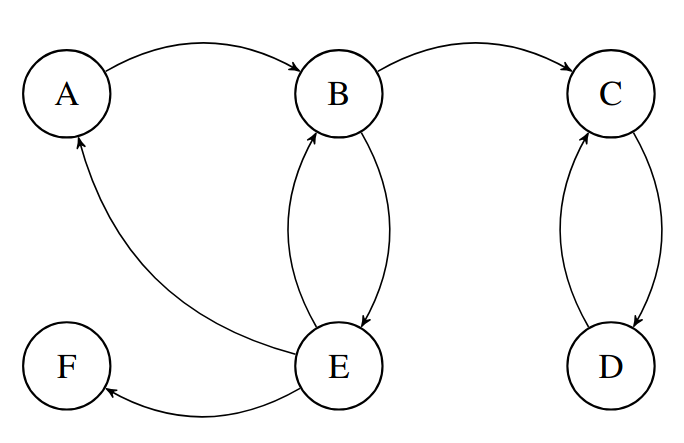

**(a)** Usando a matriz H das hiperligações, obtenha a estimativa do pagerank de cada página ao fim de

10 iterações. Relembre que deve considerar:

    **(i)** A mesma probabilidade de transição de cada página para todas as páginas seguintes possíveis; 

    **(ii)** A probabilidade da página inicial deve ser igual para todas as páginas. 

Qual/quais a(s) página(s) com maior pagerank e qual o seu valor?

**(b)** Identifique a ”spider trap” e o ”dead-end” contidos neste conjunto de páginas.

**(c)** Altere a matriz H para resolver apenas o problema do ”dead-end” e recalcule o pagerank de cada

página novamente em 10 iterações.

**(d)** Resolva agora ambos os problemas e recalcule o pagerank de cada página novamente em 10

iterações (assuma β = 0, 8).

**(e)** Calcule agora o pagerank de cada página considerando um número mínimo de iterações que garanta

que nenhum valor muda mais do que 10^(−4) em 2 iterações consecutivas. Quantos iterações são

necessárias? Compare os valores de pagerank obtidos com os da alínea anterior. O que conclui?